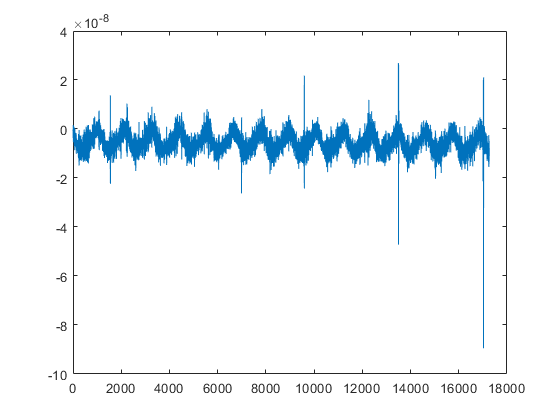

% timer start
tic
% typical header
clc;
clear;
close all;
warning('off');
dbstop if error;
format long;

date = '2019-01-01';

struc_kbr1a_c = readtable("../output/DOWR1A_2019-01-01_Y_04.txt", ...
    "FileType", "text", "ReadVariableNames", false, ...
    "ReadRowNames", false, "Delimiter", ' ', ...
    'HeaderLines', 1, "MultipleDelimsAsOne", true);
struc_kbr1a_c.Properties.VariableNames = {'gps_time', 'raw_range'};

gracefo_c = Kbr(0, 0, 0, 0, 0, 0);
gracefo_c.gps_time = struc_kbr1a_c.gps_time;
gracefo_c.dow_range = struc_kbr1a_c.raw_range;

% crn filter
length_crn = 707;
cutoff_freq = 0.1; % unit=hz
order = 7;
gracefo_c = gracefo_c.crn_filter(length_crn, cutoff_freq, order);
% compare the results
gracefo_c = gracefo_c.compare_with_1b(date);